Train ELM from human demonstration of curve tracing

clc; clear; close all;

warning('off')

elm_pathname = [pwd '/datafiles/'];
elm_file_list = dir([elm_pathname '*.trained_elm.mat']);

load('generalization_settings.mat');
load('gen_curves.mat');
gen_curves = {C_lemniscates C_cloverleaves C_ellipse C_spiral};
VK_ELM = {};
VK_CI_ELM = {};
gen_curve_curvature_zago = {};
gen_curve_speed_zago = {};
gen_curve_Y_testout_collected = {};

cm = 1/100;
mm = 1/1000;

#### Generalization across trained ELMs


for elm_j_files = 1 : length(elm_file_list)
    elm_filename = elm_file_list(elm_j_files).name

    %% Loading trained ELM
    load( strcat(elm_pathname,elm_filename) );
    Pt_samples_constant = Pt_samples;
    pstar_samples_constant = pstar_samples;

    subject_id = strsplit(elm_filename,'.trained_elm.mat');
    subject_id{1}
    generalization_duration = 100;


    %% Defining filenames
    subject_elm_gen_curves = strcat(subject_id{1},'.ELM_self_looping_new_TRAJ.mat');
    subject_fig1_elm_gen_curves_tracing = strcat(subject_id{1},'.FIG_ELM_self_looping_new_TRAJ');
    subject_fig2_elm_gen_curves_power_law = strcat(subject_id{1},'.FIG_ELM_power_law_new_TRAJ');
    h_fig1_elm_gen_fig8 = figure;
    h_power_laws_gen_curves = figure;

    for curve_idx = 1 : length(gen_curves)
    C_gen = gen_curves{curve_idx};
    GEO_gen = f_euclidean_geometry_v3(C_gen);


#### ELM Generalization: Testing phase with Self looped ELM

elm_filename = 'subject1.trained_elm.mat'

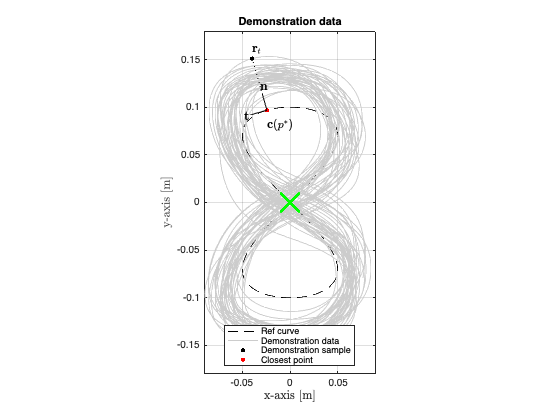

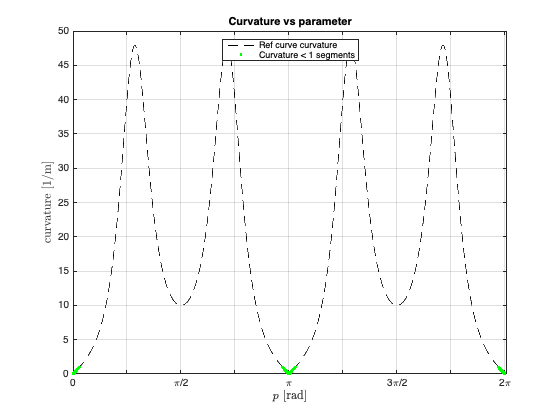

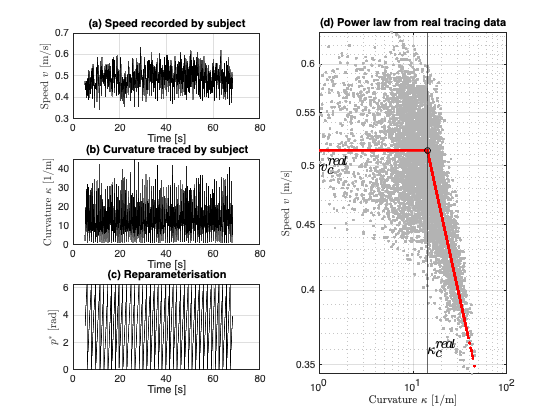

ans = 'subject1'

elm_filename = 'subject10.trained_elm.mat'

ans = 'subject10'

elm_filename = 'subject2.trained_elm.mat'

ans = 'subject2'

elm_filename = 'subject3.trained_elm.mat'

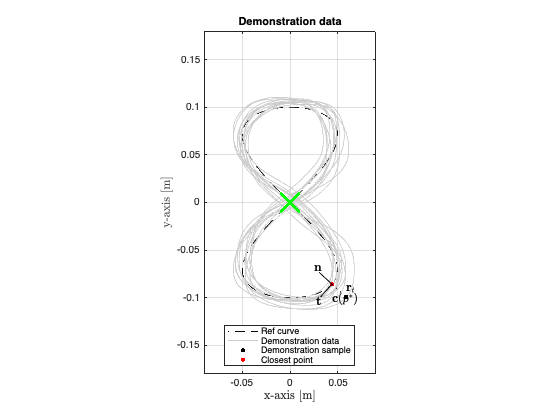

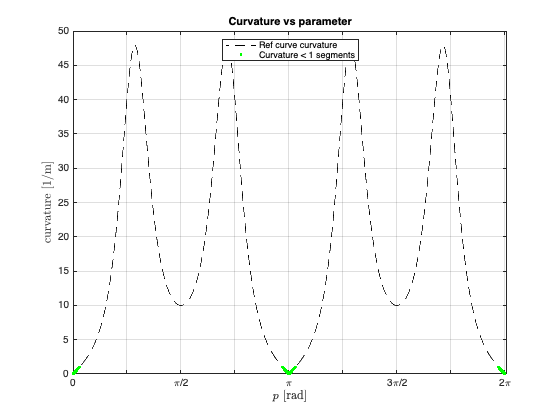

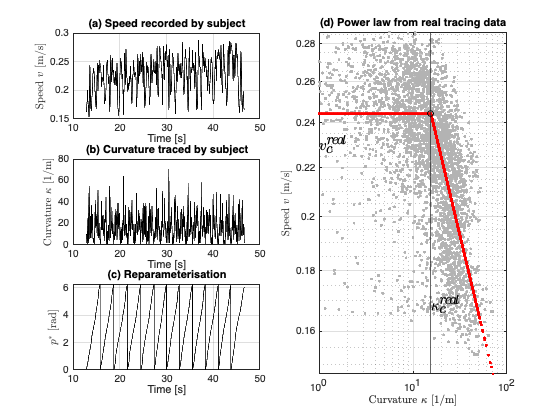

ans = 'subject3'

elm_filename = 'subject4.trained_elm.mat'

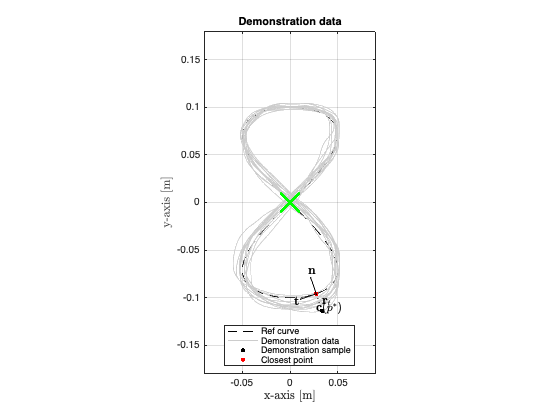

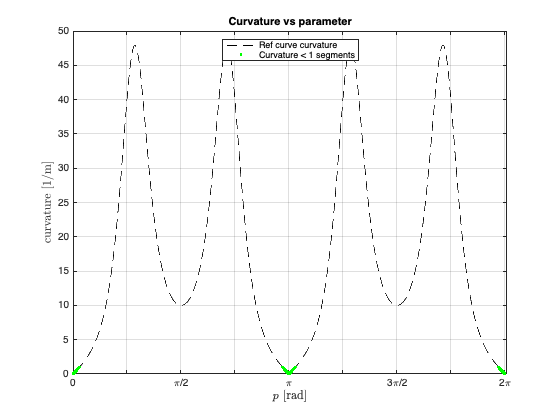

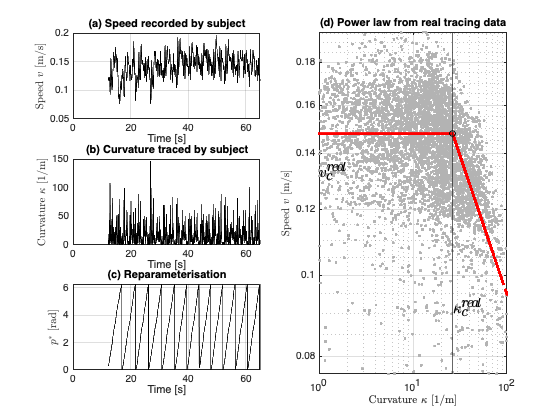

ans = 'subject4'

elm_filename = 'subject5.trained_elm.mat'

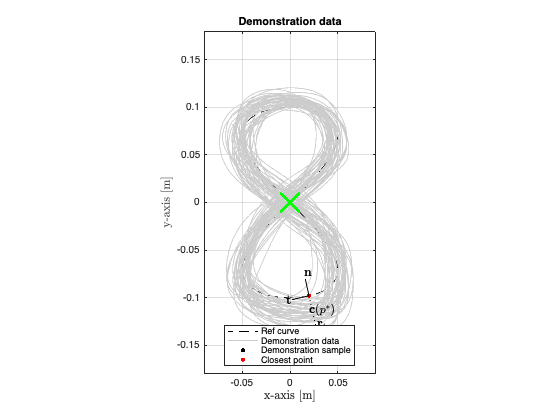

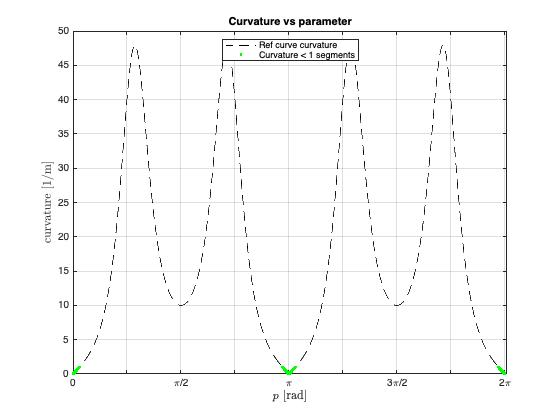

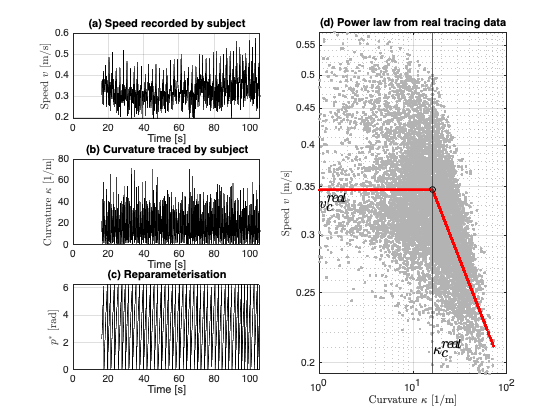

ans = 'subject5'

elm_filename = 'subject6.trained_elm.mat'

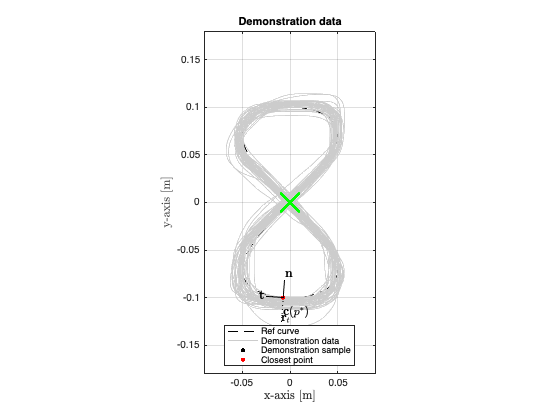

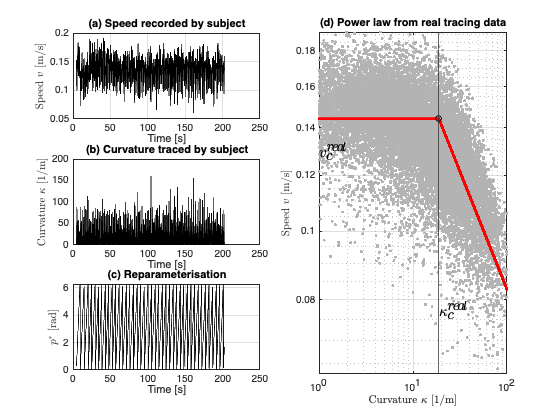

ans = 'subject6'

elm_filename = 'subject7.trained_elm.mat'

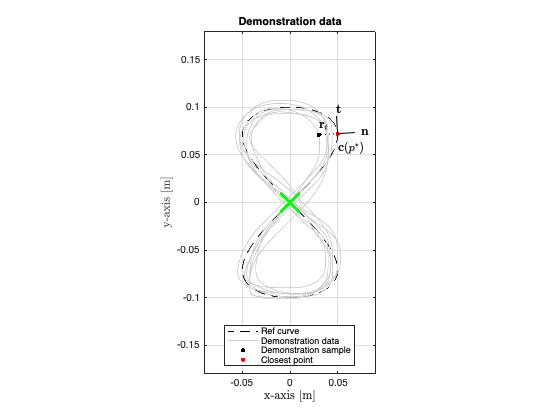

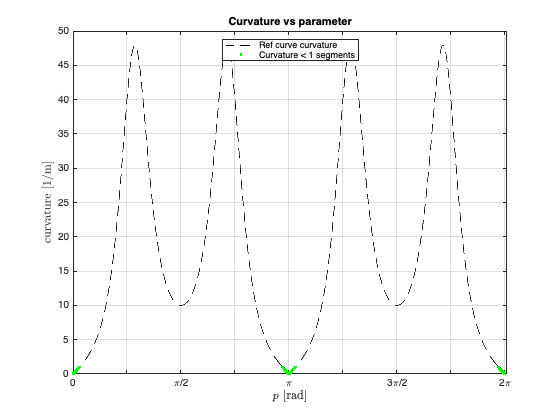

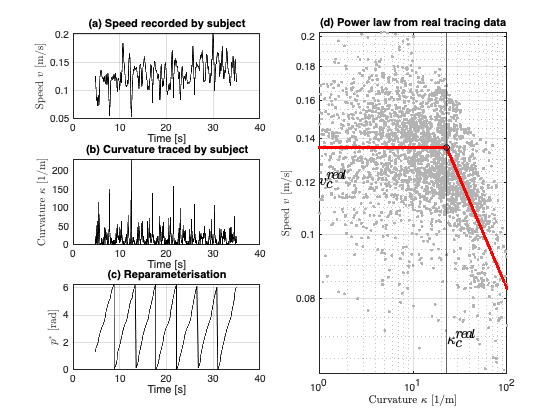

ans = 'subject7'

elm_filename = 'subject8.trained_elm.mat'

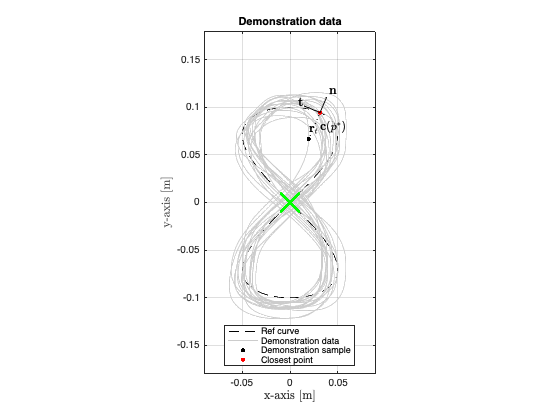

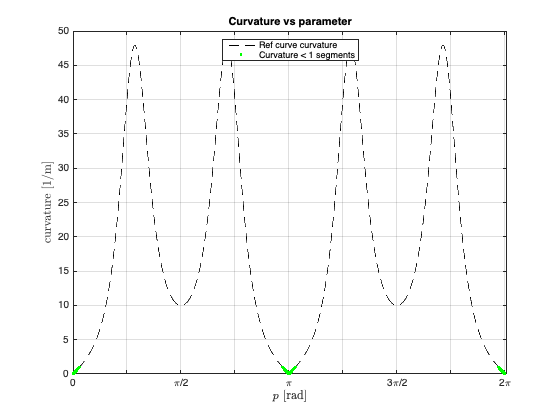

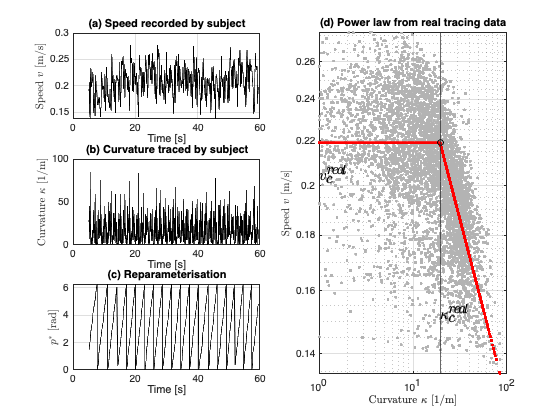

ans = 'subject8'

elm_filename = 'subject9.trained_elm.mat'

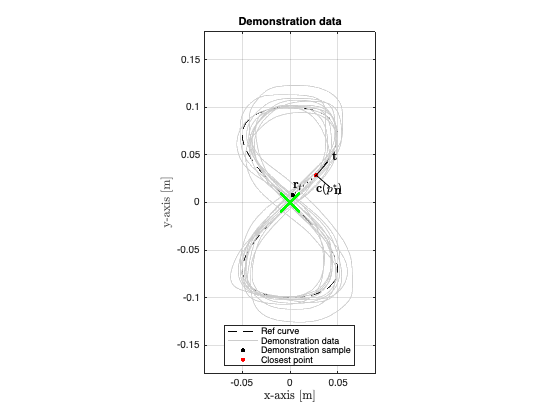

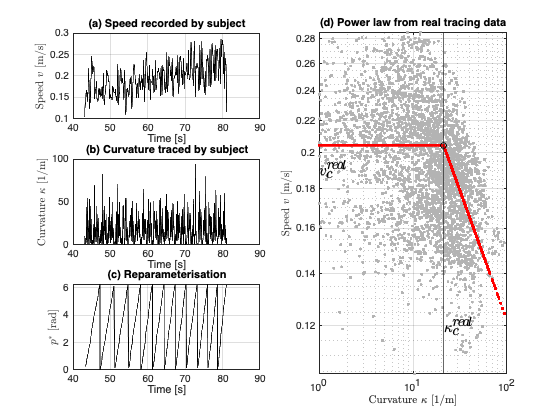

ans = 'subject9'

    speed_zago =[];
    curvature_zago = [];

    
        figure_name = strcat(subject_id{1},sprintf('.curve%d.pdf',curve_idx));
        figure2_name = strcat(subject_id{1},sprintf('.curve%d.power_law.pdf',curve_idx));
        h_fig1_elm_gen_fig8 = figure();
        h_fig2_elm_gen_fig8 = figure();


    p_range = [0:0.1:2*pi];
    curve_pts = GEO_gen.C(p_range);

    Xt = zeros(ELM.Nx, 1);
    Y_testout_collected = [];
    
    for trial = 1:20

        Y_testout = [];
        Xt = zeros(ELM.Nx,1); % zero initialisation

        
        pstar = 0; % always start self-looping from the parametric beginning of the curve
        Pt = GEO_gen.C(pstar);
        p_0 = pstar;

        pstar_per_loop = [];

        flag = 0;
        k = 1;
        Z_test_len = generalization_duration*(1/sampling_time);
        for j = 1: Z_test_len
            pstar_bak = pstar;
            pstar = fminbnd (@(p) GEO_gen.dist2(p,Pt), pstar, pstar+pi/8);
            Zt = Z_BUILDER(Pt, mod(pstar,2*pi), GEO_gen);
            Zt_norm = (Zt - mean_Z) ./ std_Z;
            Xt = ELM.Dyn (Xt, Zt_norm);
            Yt_norm = ELM.Eval(Xt) ;
            Yt = Yt_norm .* std_Y + mean_Y;
            Pt = Pt + GEO_gen.MF(mod(pstar,2*pi))*sampling_time*Yt + beta*(GEO_gen.C(pstar)-Pt);
            Y_testout(:, j) = Pt;
            pstar_per_loop = [pstar_per_loop;mod(pstar,2*pi)];
            j= j+1;
        end



## power law as in Zago et. (2018)

        range=1:length(Y_testout);
        [time_zago_trial, speed_zago_trial, curvature_zago_trial, A_zago_trial, Pt_zago_trial,Vt_zago_trial] = ...
            f_powerlaw_Zago_v4 (Y_testout,range*sampling_time,sampling_time, cutoff_frequency);
        speed_zago = [speed_zago;speed_zago_trial];
        curvature_zago = [curvature_zago;curvature_zago_trial];

        max_speed = max(speed_zago_trial);
        min_speed = min(speed_zago_trial);
        normalized_speed = (speed_zago_trial-min_speed)./(max_speed-min_speed);

    figure(h_fig1_elm_gen_fig8)
            
                h_elm_ref_curve = my2Dplot(GEO_gen.C([0:0.01:2*pi]), '--k'); hold on, grid on, axis equal;
                h_elm_tracing = scatter(Pt_zago_trial(1,:)',Pt_zago_trial(2,:)',[],[1-normalized_speed normalized_speed zeros(size(normalized_speed))]); hold on;
                colorshade = linspace(0,1,Z_test_len)';
                h_elm_tracing.Marker = '.';
                hleglines = [h_elm_ref_curve h_elm_tracing];
                colors = [1-normalized_speed normalized_speed zeros(size(normalized_speed))];
                length_color = size(colors,1);
                cbh = colorbar;
                greenredcmap = [linspace(1,0,length_color)' linspace(0,1,length_color)' zeros(length_color,1)];
                colormap(greenredcmap)
                cbh.Ticks = linspace(0, 1, 8) ; %Create 8 ticks from zero to 1
                cbh.TickLabels = num2cell(round(linspace(min_speed,max_speed, 8),2)) ;    %Replace the labels of these 8 ticks with the numbers 1 to 8
                set(cbh.XLabel,{'String','Rotation','Position'},{'Speed [m/s]',0,[2 -0.05]})
                hleg = legend(hleglines,'ref curve','elm tracing');
                hleg.Location = 'South';
                xlabel('x-axis [m]'), ylabel('y-axis [m]')
            title('ELM self-looping')

        Y_testout_collected = [Y_testout_collected Y_testout];
    end
     exportgraphics(h_fig1_elm_gen_fig8,strcat(elm_pathname, char(figure_name)),'BackgroundColor','none','ContentType','vector');


## Piecewise Linear Regression

Following [Bennequin et. al 2009], we shall consider a 2-geometry model for a powerlaw


$$v = \left\{ 
\begin{array}{lcr}
v_0 & if & k<k_c \\
v_0 \left(k/k_c\right)^{-1/3} & if & k\ge k_c
\end{array}
\right.$$


which becomes a picvewise linear model when viewed in logarithmic scales


$$\log(v) = \left\{ 
\begin{array}{lcr}
\log(v_0) & if & k<k_c \\
\log(v_0) +\frac{1}{3}\left(\log(k_c)- \log(k)\right) & if & k\ge k_c
\end{array}
\right.$$


which can be reweritten in a single equation as


$$\log(v) = \log(v_0)+\frac{1}{3}(\log(k_c)-\log(k))\frac{1+\text{ sgn}(k-k_c)}{2}$$
 

    rng('default');

    range_2 = logical(curvature_zago>curvature_threshold);
    x = (curvature_zago(range_2));
    y = (speed_zago(range_2));

        ll = 0;
        uu = 85;
        l_set = logspace(-7, 1, 50);

        Qu = prctile(x, uu);
        Ql = prctile(x, ll);

        max_ = Qu;
        min_ = Ql;
        range_3 = logical(x>min_);
        range_4 = logical(x<max_);
        x = x (range_3&range_4);
        y = y (range_3&range_4);
        ll = 5;
        uu = 95;
        

        Qu = prctile(y, uu);
        Ql = prctile(y, ll);

        max_ = Qu;
        min_ = Ql;
        range_3 = logical(y>min_);
        range_4 = logical(y<max_);
        x = x (range_3&range_4);
        y = y (range_3&range_4);
    y_o = y;
    x_o = x;
    y = log10(y_o);
    x = log10(x_o);


    len_ind = length(x);
    indeces = unique((randi(len_ind, 1, 2*len_ind)));
    if length(indeces)>floor(0.8*len_ind)
        indeces = indeces(1, 1:floor(0.8*len_ind));
    end
    all_ind = [1:len_ind];
    indeces_test = (setdiff(all_ind,indeces));
    x_train = x(indeces);
    x_test = x(indeces_test);
    y_train =y(indeces);
    y_test = y(indeces_test);
    myPWLType1 = fittype( @(LogV0, LogKc, LogK) ...
        LogV0 + 1/3*(LogKc - LogK).*(1+sign(LogK-LogKc))/2, ...
        'dependent', {'LogV'},...
        'independent', {'LogK'},...
        'coefficients', {'LogV0', 'LogKc'});
    kk = 1;
    f_test = [];
    for lambda = l_set
        fun_myPWLType1 = @(z)(mean(norm(y_train- z(1) - 1/3*(-max(x_train-z(2),0))))+lambda*abs(z(2)));
        ms = MultiStart('FunctionTolerance',2e-6,'UseParallel',true,'Display', 'off');
        problem = createOptimProblem('fmincon','x0',[log10(0.1), log10(5)],...
            'objective',fun_myPWLType1);
        [x_solv(kk).val,f(kk)] = run(ms,problem,30);
        f_test(kk) = sum(abs(y_test- x_solv(kk).val(1) - 1/3*(-max(x_test-x_solv(kk).val(2),0))));
        kk = kk + 1;

    end
    [v, ind]= min(f_test);
    x_sol = x_solv(ind).val;
    l_sol_v(elm_j_files) = l_set(ind);
    display(l_sol_v(elm_j_files));

    VK_par = 10.^x_sol;%coeffvalues(Fitting);
    VK_CI = diff(confint(Fitting, 0.95) )/2;
    display(VK_par)
    disp('Piecewise Power law parameters (Real) - critical velocity and critical curvature');
    disp("v_0 = " + num2str(VK_real(1), 2) + " \pm " + num2str(VK_CI_real(1), 2) + " m/s");
    disp("k_c = "+ num2str(VK_real(2), 2) + " \pm " + num2str(VK_CI_real(2), 2) + " m^{-1}");

    disp('Piecewise Power law parameters (ELM) - critical velocity and critical curvature');
    disp("v_0 = " + num2str(VK_par(1), 2) + " \pm " + num2str(VK_CI(1), 2) + " m/s");
    disp("k_c = "+ num2str(VK_par(2), 2) + " \pm " + num2str(VK_CI(2), 2) + " m^{-1}");


### ELM Piecewise power law plotting

  figure(h_fig2_elm_gen_fig8);
    loglog(x_o, y_o, '.', 'Color', [.7 .7 .7]); grid on; hold on;
    loglog (x_o, 10.^(log10(VK_par(1))) + 1/3*(log10(VK_par(2)) - x).*(1+sign(x-log10(VK_par(2))))/2, '.r');
    loglog(VK_par(2), VK_par(1), 'ko')
    ylabel('speed (m/s)'),xlabel('curvature [1/m]'); xlim([min(curvature_zago(range_2)) max(curvature_zago(range_2))]); ylim([min(speed_zago(range_2)) max(speed_zago(range_2))]);
    title('ELM picewise linear power law')
        text(VK_par(2)-35, min(speed_zago(range_2)) + 0.005,'$\kappa_c^{ELM}$','Interpreter','latex')
        text(min(curvature_zago(range_2)), VK_par(1)+0.005,'$v_c^{ELM}$','Interpreter','latex')
        xline(VK_par(2))
        ylabel('Speed [m/s]'),xlabel('Curvature [1/m]'); xlim([1 100]); %legend('data','-2/3');
        title('ELM power law')
      exportgraphics(h_fig2_elm_gen_fig8,strcat(elm_pathname, char(figure2_name)),'BackgroundColor','none','ContentType','vector');



        VK_ELM{curve_idx} = VK_par;
        VK_CI_ELM{curve_idx} = VK_CI;
        gen_curve_curvature_zago{curve_idx} = curvature_zago;
        gen_curve_speed_zago{curve_idx} = speed_zago;
        gen_curve_Y_testout_collected{curve_idx} = Y_testout_collected;
    end

**NOTE**: in Zago the, curvature is defined as $\mu := |{\bf c}_{ss}|$, and so it's always positive, while in the paper it's defined as $\mu :=\langle {\bf n}, {\bf c}_{ss} \rangle$

## Save real_ppl and elm_ppl data

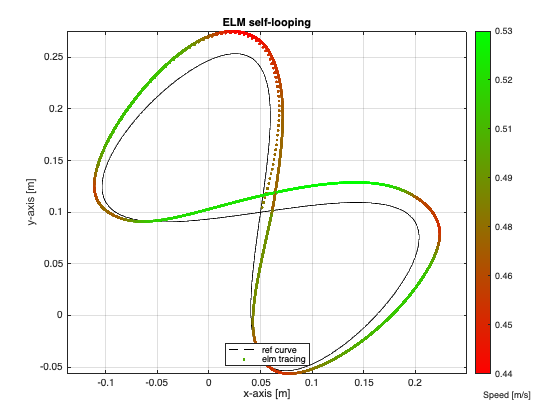

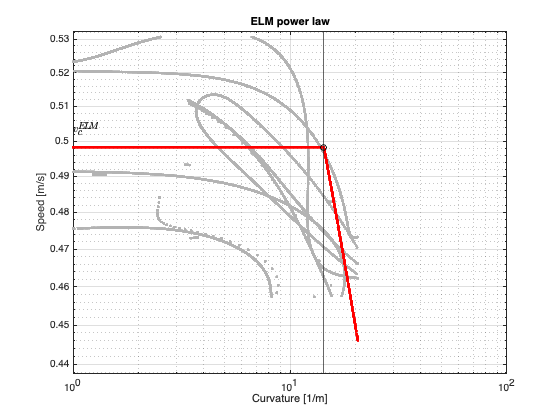

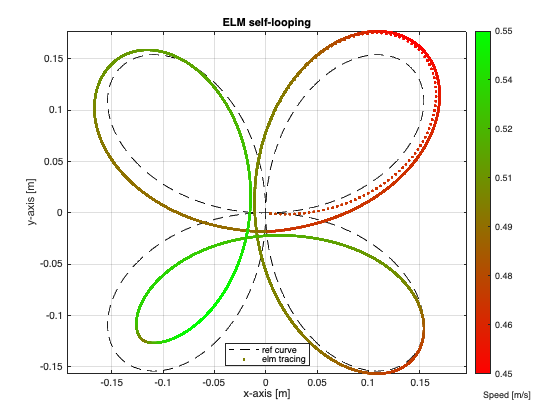

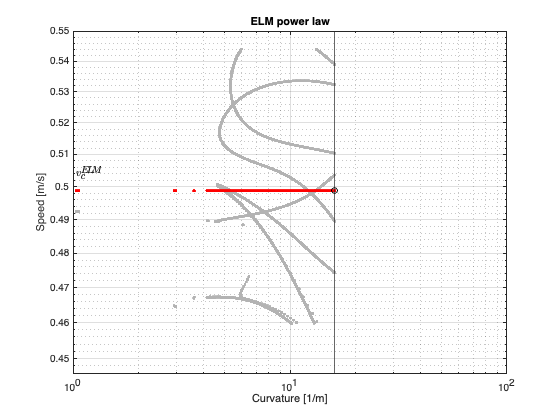

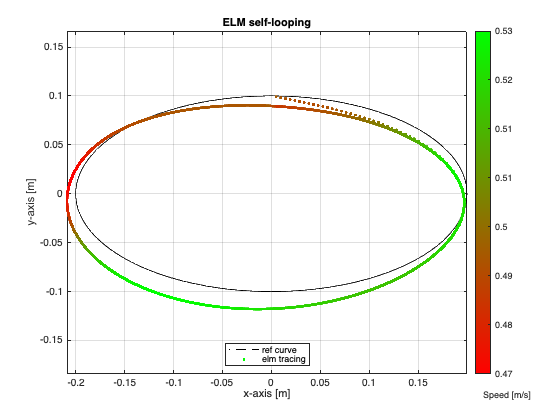

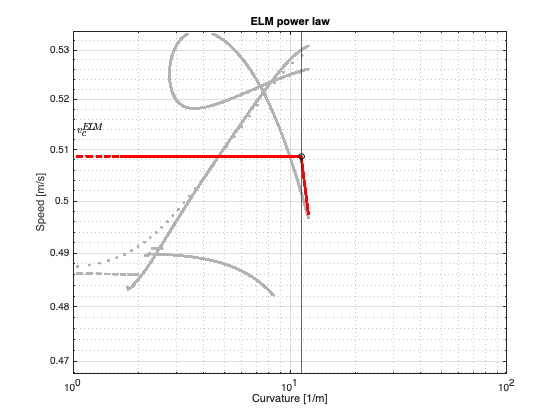

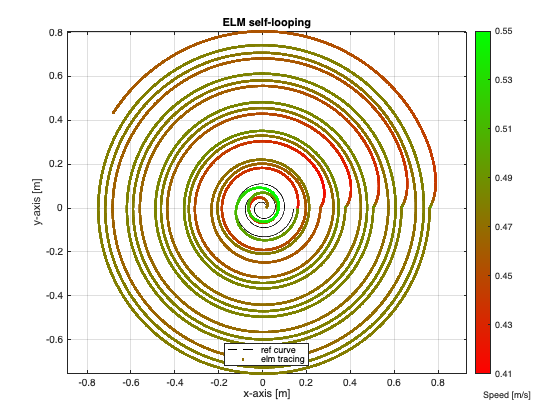

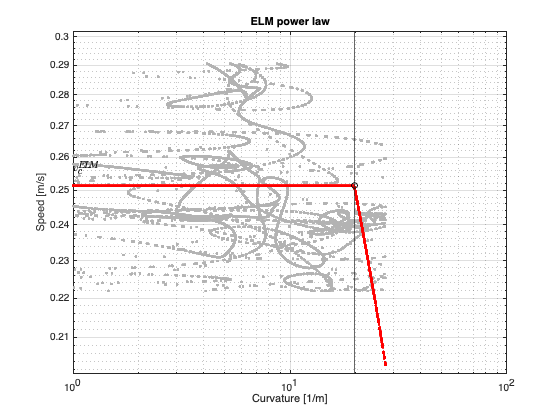

    1.0481



VK_par =     0.4983   14.3193


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.51 \pm 0.0012 m/s


k_c = 14 \pm 0.16 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.5 \pm 0.001 m/s


k_c = 14 \pm 0.0049 m^{-1}


   1.2649e-04



VK_par =     0.4988   16.0927


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.51 \pm 0.0012 m/s


k_c = 14 \pm 0.16 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.5 \pm 0.001 m/s


k_c = 16 \pm 0.0049 m^{-1}


    1.5264



VK_par =     0.5087   11.2488


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.51 \pm 0.0012 m/s


k_c = 14 \pm 0.16 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.51 \pm 0.001 m/s


k_c = 11 \pm 0.0049 m^{-1}


> In backsolveSys
In solveKKTsystem
In computeTrialStep
In barrier
In fmincon (line 886)
In globaloptim.multistart.fmultistart
In globaloptim.multistart.fmultistart
In parallel_function>make_general_channel/channel_general (line 837)
In 

    0.2330



VK_par =     0.4748    2.9775


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.51 \pm 0.0012 m/s


k_c = 14 \pm 0.16 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.47 \pm 0.001 m/s


k_c = 3 \pm 0.0049 m^{-1}


    6.8665



VK_par =     0.1028    7.1681


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.094 \pm 0.00039 m/s


k_c = 21 \pm 0.41 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.1 \pm 0.0018 m/s


k_c = 7.2 \pm 0.0087 m^{-1}


    4.7149



VK_par =     0.0937    9.0365


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.094 \pm 0.00039 m/s


k_c = 21 \pm 0.41 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.094 \pm 0.0018 m/s


k_c = 9 \pm 0.0087 m^{-1}


   6.2506e-06



VK_par =     0.1059    7.9071


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.094 \pm 0.00039 m/s


k_c = 21 \pm 0.41 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.11 \pm 0.0018 m/s


k_c = 7.9 \pm 0.0087 m^{-1}


    0.0037



VK_par =     0.0877    8.3737


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.094 \pm 0.00039 m/s


k_c = 21 \pm 0.41 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.088 \pm 0.0018 m/s


k_c = 8.4 \pm 0.0087 m^{-1}


    0.3393



VK_par =     0.2514   19.7515


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.27 \pm 0.0006 m/s


k_c = 15 \pm 0.15 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.25 \pm 0.00098 m/s


k_c = 20 \pm 0.0042 m^{-1}


    0.0754



VK_par =     0.2416   19.9888


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.27 \pm 0.0006 m/s


k_c = 15 \pm 0.15 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.24 \pm 0.00098 m/s


k_c = 20 \pm 0.0042 m^{-1}


    1.5264



VK_par =     0.2415   16.6479


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.27 \pm 0.0006 m/s


k_c = 15 \pm 0.15 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.24 \pm 0.00098 m/s


k_c = 17 \pm 0.0042 m^{-1}


    0.0168



VK_par =     0.2371    4.8491


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.27 \pm 0.0006 m/s


k_c = 15 \pm 0.15 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.24 \pm 0.00098 m/s


k_c = 4.8 \pm 0.0042 m^{-1}


    6.8665



VK_par =     0.2285   12.0002


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.24 \pm 0.0014 m/s


k_c = 16 \pm 0.36 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.23 \pm 0.0024 m/s


k_c = 12 \pm 0.01 m^{-1}


   2.9471e-06



VK_par =     0.2303   12.1556


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.24 \pm 0.0014 m/s


k_c = 16 \pm 0.36 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.23 \pm 0.0024 m/s


k_c = 12 \pm 0.01 m^{-1}


   4.2919e-06



VK_par =     0.2327   10.9336


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.24 \pm 0.0014 m/s


k_c = 16 \pm 0.36 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.23 \pm 0.0024 m/s


k_c = 11 \pm 0.01 m^{-1}


    0.0115



VK_par =     0.2195    4.8621


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.24 \pm 0.0014 m/s


k_c = 16 \pm 0.36 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.22 \pm 0.0024 m/s


k_c = 4.9 \pm 0.01 m^{-1}


    0.7197



VK_par =     0.1457   21.2196


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.15 \pm 0.00045 m/s


k_c = 26 \pm 0.48 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.15 \pm 0.0013 m/s


k_c = 21 \pm 0.0079 m^{-1}


    1.5264



VK_par =     0.2125    3.7221


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.15 \pm 0.00045 m/s


k_c = 26 \pm 0.48 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.21 \pm 0.0013 m/s


k_c = 3.7 \pm 0.0079 m^{-1}


    0.3393



VK_par =     0.1521   22.3141


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.15 \pm 0.00045 m/s


k_c = 26 \pm 0.48 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.15 \pm 0.0013 m/s


k_c = 22 \pm 0.0079 m^{-1}


    0.7197



VK_par =     0.1596    1.0000


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.15 \pm 0.00045 m/s


k_c = 26 \pm 0.48 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.16 \pm 0.0013 m/s


k_c = 1 \pm 0.0079 m^{-1}


   3.0888e-07



VK_par =     0.3243   79.9685


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.35 \pm 0.0015 m/s


k_c = 16 \pm 0.32 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.32 \pm 0.0019 m/s


k_c = 80 \pm 0.0085 m^{-1}


    4.7149



VK_par =     0.3692   11.7431


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.35 \pm 0.0015 m/s


k_c = 16 \pm 0.32 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.37 \pm 0.0019 m/s


k_c = 12 \pm 0.0085 m^{-1}


    0.4942



VK_par =     0.3293    8.0171


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.35 \pm 0.0015 m/s


k_c = 16 \pm 0.32 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.33 \pm 0.0019 m/s


k_c = 8 \pm 0.0085 m^{-1}


   9.5410e-07



VK_par =     0.0114    5.9770


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.35 \pm 0.0015 m/s


k_c = 16 \pm 0.32 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.011 \pm 0.0019 m/s


k_c = 6 \pm 0.0085 m^{-1}


    2.2230



VK_par =     0.1469   13.4955


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.14 \pm 0.00036 m/s


k_c = 19 \pm 0.22 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.15 \pm 0.0011 m/s


k_c = 13 \pm 0.0051 m^{-1}


    3.2375



VK_par =     0.1184    8.8758


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.14 \pm 0.00036 m/s


k_c = 19 \pm 0.22 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.12 \pm 0.0011 m/s


k_c = 8.9 \pm 0.0051 m^{-1}


    1.0481



VK_par =     0.1505    9.9329


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.14 \pm 0.00036 m/s


k_c = 19 \pm 0.22 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.15 \pm 0.0011 m/s


k_c = 9.9 \pm 0.0051 m^{-1}


    0.0012



VK_par =     0.0793    7.7701


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.14 \pm 0.00036 m/s


k_c = 19 \pm 0.22 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.079 \pm 0.0011 m/s


k_c = 7.8 \pm 0.0051 m^{-1}


    3.2375



VK_par =     0.1341   11.8653


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.14 \pm 0.00057 m/s


k_c = 23 \pm 0.51 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.13 \pm 0.0018 m/s


k_c = 12 \pm 0.0097 m^{-1}


    0.1600



VK_par =     0.1349   15.2588


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.14 \pm 0.00057 m/s


k_c = 23 \pm 0.51 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.13 \pm 0.0018 m/s


k_c = 15 \pm 0.0097 m^{-1}


    0.0168



VK_par =     0.1361   13.3033


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.14 \pm 0.00057 m/s


k_c = 23 \pm 0.51 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.14 \pm 0.0018 m/s


k_c = 13 \pm 0.0097 m^{-1}


    0.0356



VK_par =     0.1242    6.1308


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.14 \pm 0.00057 m/s


k_c = 23 \pm 0.51 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.12 \pm 0.0018 m/s


k_c = 6.1 \pm 0.0097 m^{-1}


   2.9471e-06



VK_par =     0.1996   18.9314


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.22 \pm 0.00089 m/s


k_c = 19 \pm 0.37 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.2 \pm 0.0018 m/s


k_c = 19 \pm 0.0084 m^{-1}


    3.2375



VK_par =     0.2007   13.2484


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.22 \pm 0.00089 m/s


k_c = 19 \pm 0.37 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.2 \pm 0.0018 m/s


k_c = 13 \pm 0.0084 m^{-1}


   1.0000e-07



VK_par =     0.2016    9.6865


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.22 \pm 0.00089 m/s


k_c = 19 \pm 0.37 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.2 \pm 0.0018 m/s


k_c = 9.7 \pm 0.0084 m^{-1}


    4.7149



VK_par =     0.1761    3.7253


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.22 \pm 0.00089 m/s


k_c = 19 \pm 0.37 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.18 \pm 0.0018 m/s


k_c = 3.7 \pm 0.0084 m^{-1}


    4.7149



VK_par =     0.2016   11.2062


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.2 \pm 0.0014 m/s


k_c = 21 \pm 0.71 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.2 \pm 0.0029 m/s


k_c = 11 \pm 0.015 m^{-1}


    0.1600



VK_par =     0.2055   13.1031


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.2 \pm 0.0014 m/s


k_c = 21 \pm 0.71 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.21 \pm 0.0029 m/s


k_c = 13 \pm 0.015 m^{-1}


   6.2506e-06



VK_par =     0.2012   11.0083


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.2 \pm 0.0014 m/s


k_c = 21 \pm 0.71 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.2 \pm 0.0029 m/s


k_c = 11 \pm 0.015 m^{-1}


    0.0754



VK_par =     0.1852    4.7543


Piecewise Power law parameters (Real) - critical velocity and critical curvature


v_0 = 0.2 \pm 0.0014 m/s


k_c = 21 \pm 0.71 m^{-1}


Piecewise Power law parameters (ELM) - critical velocity and critical curvature


v_0 = 0.19 \pm 0.0029 m/s


k_c = 4.8 \pm 0.015 m^{-1}



    save([elm_pathname char(subject_elm_gen_curves)],'VK_real','VK_CI_real','VK_ELM','VK_CI_ELM','gen_curve_curvature_zago','gen_curve_speed_zago','sampling_time','gen_curve_Y_testout_collected');
end